# **Data processing, No. 1 borehole in Jintan City**

close all
clc
clear
warning off
format long

## Data format (important!), Sort by filed test project

- nzsensing DTS_+Tstart+_+Tend+.mat or Ultima DTS_+Tstart+_+Tend+.mat; Save it as basic data

- Test information = Info.mat

- Data in borehole and the certain time = Test+number1+Process+number2.timeseconds/temperarure/anti-temperature/depth/anti-depth.mat; number1 = the number of test in one field project; number2 = 1/2, 1 = time parting, and 2 = depth parting

- Thermal response test in borehole and the certain time = Heat + the contents in (3)

- Natural temperarture in borehole and the certain time = Natural + the contents in (3)

- Data tranform in Natural temperature in our database (jintan.mat). jintan.bore+borehole number+.depth+yyyymmdd = NaturalProcess2.depth; jintan.bore+borehole number+.temperature+yyyymmdd = mean(NaturalProcess2.temperature(:,1:end),2);

- Thermal conducivity results. TC.begin_t+number*, TC.finish_t+number*, number* is the serial number of thermal response test; TC.value+number*, number* is the serial number of thermal response test

- Save above data (every field project). jintan.bore+borehole number+.depth+yyyymmdd = Natural+number1+Process+number2.depth; jintan.bore+borehole number+.temperature+yyyymmdd = mean(NaturalProcess2.temperature(:,1:end),2)

- Data tranform in Thermal Conductivity in our database (jintan.mat). jintan.bore+borehole number+.thermalConductivity+yyyymmdd= TC.value

## Fileld Project-202207

### Temperature observation; Ultima DTS

#### 1 Load data

[filename,filepath] = uigetfile({'*.xml','silixa XML files(*.xml)'},"MultiSelect","on");
n = length(filename);
dom = xmlread([filepath,char(filename(1))]);
datas = dom.getElementsByTagName('data');
m = datas.getLength;
startDateTimeStrings = strings(1,n);
RT = strings(1,n);
RTP1 = strings(1,n);
RTP2 = strings(1,n);

LAF = zeros(m,n); % length along fiber
ST = zeros(m,n); % Stokes intensity
AST = zeros(m,n); % anti-Stokes intensity
REV_ST = zeros(m,n); % reverse Stokes intensity
REV_AST = zeros(m,n); % reverse anti-Stokes intensity
TMP = zeros(m,n); % DTS temperature

progressbar
for j=1:n
    dom=xmlread([filepath,char(filename(j))]);
    datas=dom.getElementsByTagName('data');
    % m=datas.getLength;
    startDateTime=dom.getElementsByTagName('startDateTimeIndex');
    startDateTimeStrings(1,j)=char(startDateTime.item(0).getFirstChild.getData);
    startTime = datetime(startDateTimeStrings,'InputFormat','uuuu-MM-dd''T''HH:mm:ss.SSSXXXX','TimeZone','UTC+8');
    referenceTemperature = dom.getElementsByTagName('referenceTemperature');
    RT(1,j)=char(referenceTemperature.item(0).getFirstChild.getData);
    probe1Temperature = dom.getElementsByTagName('probe1Temperature');
    RTP1(1,j)=char(probe1Temperature.item(0).getFirstChild.getData);
    probe2Temperature = dom.getElementsByTagName('probe2Temperature');
    RTP2(1,j)=char(probe2Temperature.item(0).getFirstChild.getData);
    
    for i=0:m-1 % XML中索引从0开始
        dataValues=char(datas.item(i).getFirstChild.getData); % 读取节点下的数据
        dataValues=strip(dataValues); % 删除首尾空白字符
        dataValue=split(dataValues,','); % 以','分割字符串
        LAF(i+1,j)=str2double(cell2mat(dataValue(1))); % 保存各数据
        ST(i+1,j)=str2double(cell2mat(dataValue(2)));
        AST(i+1,j)=str2double(cell2mat(dataValue(3)));
        TMP(i+1,j)=str2double(cell2mat(dataValue(4)));
    end
    progressbar(j/n)
end
RT = str2double(RT);
RTP1 = str2double(RTP1);
RTP2 = str2double(RTP2);

DTS.startTime=startTime; % 
DTS.RT=RT;
DTS.RTP1=RTP1;
DTS.RTP2=RTP2;
DTS.LAF=LAF; %
DTS.ST=ST;
DTS.AST=AST;
DTS.TMP=TMP; %

% [savename,savepath]=uiputfile('*.mat');
Tstart=replace(replace(replace(char(startTime(1)),'-',''),' ',''),':','');
Tend=replace(replace(replace(char(startTime(end)),'-',''),' ',''),':','');
savename=['Ultima DTS_',Tstart,'_',Tend,'.mat'];
save(savename,'DTS');

clearvars -except DTS;

#### 2 Time information

Info.start_test = '2022/07/28  16:15:00'; % apply the test
Info.end_test = '2022/07/28  17:45:00'; % finish the test
clearvars -except Info DTS;

#### 3 Extract the data in time

p = 0;
for i = 1:length(DTS.startTime)
    t_processing = DTS.startTime(1,i);
    if t_processing>=Info.start_test && t_processing<=Info.end_test
        p = p+1;
        date(1,p) = DTS.startTime(1,i);
        temperature_processing(:,p) = DTS.TMP(1:end,i);
        t_processed = date(1,p);
        t_processed = char(t_processed);
        t_processed = datetime(t_processing,'InputFormat','yyyy/MM/dd HH:mm:ss');
        time_seconds(1,p) = seconds(t_processed-Info.start_test);
    end
end

Test1Process1.timeseconds = time_seconds;
Test1Process1.temperature = temperature_processing;
clearvars -except Test1Process1 Info DTS;

#### 4 Check the length

figure(1)
plot(DTS.LAF,Test1Process1.temperature(:,1))
hold on
plot(DTS.LAF,Test1Process1.temperature(:,20))
hold off
ylim([10 50])
title('温度-时间曲线')
xlabel('length (m)');
ylabel('Temperature (^oC)');
% 202207Borehole [80.714,231.709]

#### 5 Extract the data in length

q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=80.714 && DTS.LAF(k,1)<=231.709
        q = q+1;
        Test1Process2.depth(q,1) = DTS.LAF(k,1)-80.714;
        Test1Process2.temperature(q,:) = Test1Process1.temperature(k,:);
    end
end

clear k q

#### Chech the results

figure(2)
color_line = turbo(3);
plot(Test1Process2.temperature(:,1),Test1Process2.depth,"Color",color_line(1,:),'LineWidth',0.75)
hold on 
plot(Test1Process2.temperature(:,80),Test1Process2.depth,"Color",color_line(2,:),'LineWidth',0.75)
hold on
plot(Test1Process2.temperature(:,end),Test1Process2.depth,"Color",color_line(3,:),'LineWidth',0.75,"LineStyle","--")
hold off
set(gca,'YDir','reverse');
ylim([0 100])
xlim([15 30])
title('TDP')
ylabel('Depth (m)');
xlabel('Temperature (^oC)',"Clipping","on");
set(gcf,'unit','centimeters','position',[5 5 8 16]);
clear color_line

figure(3)
plot(Test1Process1.timeseconds,Test1Process2.temperature(159,:))
title('TTP (40 m)')
xlabel('Time (s)');
ylabel('Temperature (^oC)');
set(gcf,'unit','centimeters','position',[5 5 10 6]);

#### 6 Data transform

load changzhou.mat changzhou
changzhou.bore4.depth20220728 = Test1Process2.depth;
changzhou.bore4.temperature202207281700 = mean(Test1Process2.temperature(:,66:end),2);
save changzhou.mat changzhou

#### 7 Save the processed data

save data_changzhou_04_20220728_process_202301091708.mat

#### 8 Next one

clear 
clc

## Fileld Project-202209

### Temperature observation; Ultima DTS

#### 1 Load data

[filename,filepath] = uigetfile({'*.xml','silixa XML files(*.xml)'},"MultiSelect","on");
n = length(filename);
dom = xmlread([filepath,char(filename(1))]);
datas = dom.getElementsByTagName('data');
m = datas.getLength;
startDateTimeStrings = strings(1,n);
RT = strings(1,n);
RTP1 = strings(1,n);
RTP2 = strings(1,n);

LAF = zeros(m,n); % length along fiber
ST = zeros(m,n); % Stokes intensity
AST = zeros(m,n); % anti-Stokes intensity
REV_ST = zeros(m,n); % reverse Stokes intensity
REV_AST = zeros(m,n); % reverse anti-Stokes intensity
TMP = zeros(m,n); % DTS temperature

progressbar
for j=1:n
    dom=xmlread([filepath,char(filename(j))]);
    datas=dom.getElementsByTagName('data');
    % m=datas.getLength;
    startDateTime=dom.getElementsByTagName('startDateTimeIndex');
    startDateTimeStrings(1,j)=char(startDateTime.item(0).getFirstChild.getData);
    startTime = datetime(startDateTimeStrings,'InputFormat','uuuu-MM-dd''T''HH:mm:ss.SSSXXXX','TimeZone','UTC+8');
    referenceTemperature = dom.getElementsByTagName('referenceTemperature');
    RT(1,j)=char(referenceTemperature.item(0).getFirstChild.getData);
    probe1Temperature = dom.getElementsByTagName('probe1Temperature');
    RTP1(1,j)=char(probe1Temperature.item(0).getFirstChild.getData);
    probe2Temperature = dom.getElementsByTagName('probe2Temperature');
    RTP2(1,j)=char(probe2Temperature.item(0).getFirstChild.getData);
    
    for i=0:m-1 % XML中索引从0开始
        dataValues=char(datas.item(i).getFirstChild.getData); % 读取节点下的数据
        dataValues=strip(dataValues); % 删除首尾空白字符
        dataValue=split(dataValues,','); % 以','分割字符串
        LAF(i+1,j)=str2double(cell2mat(dataValue(1))); % 保存各数据
        ST(i+1,j)=str2double(cell2mat(dataValue(2)));
        AST(i+1,j)=str2double(cell2mat(dataValue(3)));
        TMP(i+1,j)=str2double(cell2mat(dataValue(4)));
    end
    progressbar(j/n)
end
RT = str2double(RT);
RTP1 = str2double(RTP1);
RTP2 = str2double(RTP2);

DTS.startTime=startTime;
DTS.RT=RT;
DTS.RTP1=RTP1;
DTS.RTP2=RTP2;
DTS.LAF=LAF;
DTS.ST=ST;
DTS.AST=AST;
DTS.TMP=TMP;

% [savename,savepath]=uiputfile('*.mat');
Tstart=replace(replace(replace(char(startTime(1)),'-',''),' ',''),':','');
Tend=replace(replace(replace(char(startTime(end)),'-',''),' ',''),':','');
savename=['Ultima DTS_',Tstart,'_',Tend,'.mat'];
save(savename,'DTS');

clearvars -except DTS;

#### 2 Time information

Info.start_test = '2022/09/23  15:45:00'; % apply the test
Info.end_test = '2022/09/23  18:45:00'; % finish the test
clearvars -except Info DTS;

#### 3 Extract the data in time

p = 0;
for i = 1:length(DTS.startTime)
    t_processing = DTS.startTime(1,i);
    if t_processing>=Info.start_test && t_processing<=Info.end_test
        p = p+1;
        date(1,p) = DTS.startTime(1,i);
        temperature_processing(:,p) = DTS.TMP(1:end,i);
        t_processed = date(1,p);
        t_processed = char(t_processed);
        t_processed = datetime(t_processing,'InputFormat','yyyy/MM/dd HH:mm:ss');
        time_seconds(1,p) = seconds(t_processed-Info.start_test);
    end
end

Test1Process1.timeseconds = time_seconds;
Test1Process1.temperature = temperature_processing;
clearvars -except Test1Process1 Info DTS;

#### 4 Check the length

figure(1)
plot(DTS.LAF,Test1Process1.temperature(:,1))
hold on
plot(DTS.LAF,Test1Process1.temperature(:,20))
hold off
ylim([10 50])
title('温度-时间曲线')
xlabel('length (m)');
ylabel('Temperature (^oC)');
% 202207Borehole [82.439,233.434]

#### 5 Extract the data in length

q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=82.439 && DTS.LAF(k,1)<=233.434
        q = q+1;
        Test1Process2.depth(q,1) = DTS.LAF(k,1)-82.439;
        Test1Process2.temperature(q,:) = Test1Process1.temperature(k,:);
    end
end

clear k q

#### Chech the results

figure(2)
color_line = turbo(3);
plot(Test1Process2.temperature(:,1),Test1Process2.depth,"Color",color_line(1,:),'LineWidth',0.75)
hold on 
plot(Test1Process2.temperature(:,80),Test1Process2.depth,"Color",color_line(2,:),'LineWidth',0.75)
hold on
plot(Test1Process2.temperature(:,end),Test1Process2.depth,"Color",color_line(3,:),'LineWidth',0.75,"LineStyle","--")
hold off
set(gca,'YDir','reverse');
ylim([0 100])
xlim([15 30])
title('TDP')
ylabel('Depth (m)');
xlabel('Temperature (^oC)',"Clipping","on");
set(gcf,'unit','centimeters','position',[5 5 8 16]);
clear color_line

figure(3)
plot(Test1Process1.timeseconds,Test1Process2.temperature(159,:))
title('TTP (40 m)')
xlabel('Time (s)');
ylabel('Temperature (^oC)');
set(gcf,'unit','centimeters','position',[5 5 10 6]);

#### 6 Data transform

load changzhou.mat changzhou
changzhou.bore4.depth20220923 = Test1Process2.depth;
changzhou.bore4.temperature202209231715 = mean(Test1Process2.temperature(:,1:end),2);
save changzhou.mat changzhou

#### 7 Save the processed data

save data_changzhou_04_20220923_process_202301091730.mat

#### 8 Next one

clear 
clc

## Fileld Project-202211

### Temperature observation; Ultima DTS

#### 1 Load data

[filename,filepath] = uigetfile({'*.xml','silixa XML files(*.xml)'},"MultiSelect","on");
n = length(filename);
dom = xmlread([filepath,char(filename(1))]);
datas = dom.getElementsByTagName('data');
m = datas.getLength;
startDateTimeStrings = strings(1,n);
RT = strings(1,n);
RTP1 = strings(1,n);
RTP2 = strings(1,n);

LAF = zeros(m,n); % length along fiber
ST = zeros(m,n); % Stokes intensity
AST = zeros(m,n); % anti-Stokes intensity
REV_ST = zeros(m,n); % reverse Stokes intensity
REV_AST = zeros(m,n); % reverse anti-Stokes intensity
TMP = zeros(m,n); % DTS temperature

progressbar
for j=1:n
    dom=xmlread([filepath,char(filename(j))]);
    datas=dom.getElementsByTagName('data');
    % m=datas.getLength;
    startDateTime=dom.getElementsByTagName('startDateTimeIndex');
    startDateTimeStrings(1,j)=char(startDateTime.item(0).getFirstChild.getData);
    startTime = datetime(startDateTimeStrings,'InputFormat','uuuu-MM-dd''T''HH:mm:ss.SSSXXXX','TimeZone','UTC+8');
    referenceTemperature = dom.getElementsByTagName('referenceTemperature');
    RT(1,j)=char(referenceTemperature.item(0).getFirstChild.getData);
    probe1Temperature = dom.getElementsByTagName('probe1Temperature');
    RTP1(1,j)=char(probe1Temperature.item(0).getFirstChild.getData);
    probe2Temperature = dom.getElementsByTagName('probe2Temperature');
    RTP2(1,j)=char(probe2Temperature.item(0).getFirstChild.getData);
    
    for i=0:m-1 % XML中索引从0开始
        dataValues=char(datas.item(i).getFirstChild.getData); % 读取节点下的数据
        dataValues=strip(dataValues); % 删除首尾空白字符
        dataValue=split(dataValues,','); % 以','分割字符串
        LAF(i+1,j)=str2double(cell2mat(dataValue(1))); % 保存各数据
        ST(i+1,j)=str2double(cell2mat(dataValue(2)));
        AST(i+1,j)=str2double(cell2mat(dataValue(3)));
        TMP(i+1,j)=str2double(cell2mat(dataValue(4)));
    end
    progressbar(j/n)
end
RT = str2double(RT);
RTP1 = str2double(RTP1);
RTP2 = str2double(RTP2);

DTS.startTime=startTime;
DTS.RT=RT;
DTS.RTP1=RTP1;
DTS.RTP2=RTP2;
DTS.LAF=LAF;
DTS.ST=ST;
DTS.AST=AST;
DTS.TMP=TMP;

% [savename,savepath]=uiputfile('*.mat');
Tstart=replace(replace(replace(char(startTime(1)),'-',''),' ',''),':','');
Tend=replace(replace(replace(char(startTime(end)),'-',''),' ',''),':','');
savename=['Ultima DTS_',Tstart,'_',Tend,'.mat'];
save(savename,'DTS');

clearvars -except DTS;

#### 2 Time information

Info.start_test = '2022/11/24  20:45:00'; % apply the test
Info.end_test = '2022/11/24  21:45:00'; % finish the test
clearvars -except Info DTS;

#### 3 Extract the data in time

p = 0;
for i = 1:length(DTS.startTime)
    t_processing = DTS.startTime(1,i);
    if t_processing>=Info.start_test && t_processing<=Info.end_test
        p = p+1;
        date(1,p) = DTS.startTime(1,i);
        temperature_processing(:,p) = DTS.TMP(1:end,i);
        t_processed = date(1,p);
        t_processed = char(t_processed);
        t_processed = datetime(t_processing,'InputFormat','yyyy/MM/dd HH:mm:ss');
        time_seconds(1,p) = seconds(t_processed-Info.start_test);
    end
end

Test1Process1.timeseconds = time_seconds;
Test1Process1.temperature = temperature_processing;
clearvars -except Test1Process1 Info DTS;

#### 4 Check the length

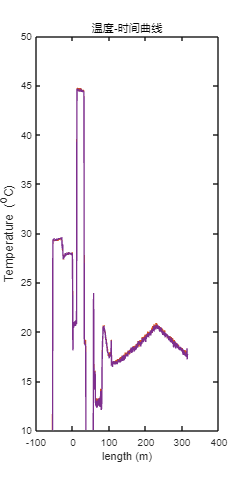

figure(1)
plot(DTS.LAF,Test1Process1.temperature(:,1))
hold on
plot(DTS.LAF,Test1Process1.temperature(:,20))
hold off
ylim([10 50])
title('温度-时间曲线')
xlabel('length (m)');
ylabel('Temperature (^oC)');

% 202207Borehole [78.626,229.621]

#### 5 Extract the data in length

q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=78.626 && DTS.LAF(k,1)<=229.621
        q = q+1;
        Test1Process2.depth(q,1) = DTS.LAF(k,1)-78.626;
        Test1Process2.temperature(q,:) = Test1Process1.temperature(k,:);
    end
end

clear k q

#### Chech the results

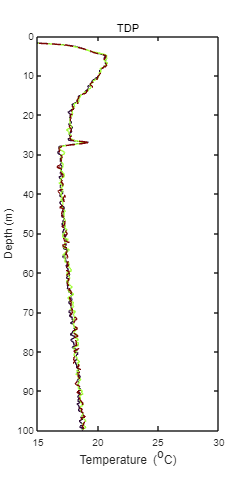

figure(2)
color_line = turbo(3);
plot(Test1Process2.temperature(:,1),Test1Process2.depth,"Color",color_line(1,:),'LineWidth',0.75)
hold on 
plot(Test1Process2.temperature(:,80),Test1Process2.depth,"Color",color_line(2,:),'LineWidth',0.75)
hold on
plot(Test1Process2.temperature(:,end),Test1Process2.depth,"Color",color_line(3,:),'LineWidth',0.75,"LineStyle","--")
hold off
set(gca,'YDir','reverse');
ylim([0 100])
xlim([15 30])
title('TDP')
ylabel('Depth (m)');
xlabel('Temperature (^oC)',"Clipping","on");

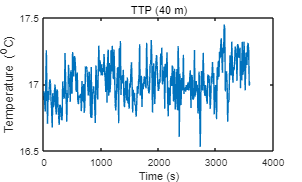

set(gcf,'unit','centimeters','position',[5 5 8 16]);
clear color_line

figure(3)
plot(Test1Process1.timeseconds,Test1Process2.temperature(159,:))
title('TTP (40 m)')
xlabel('Time (s)');
ylabel('Temperature (^oC)');

set(gcf,'unit','centimeters','position',[5 5 10 6]);

#### 6 Data transform

load changzhou.mat changzhou
changzhou.bore4.depth20221124 = Test1Process2.depth;
changzhou.bore4.temperature202211242115 = mean(Test1Process2.temperature(:,1:end),2);
save changzhou.mat changzhou

#### 7 Save the processed data

save data_changzhou_04_20221124_process_202301091745.mat

#### 8 Next one

clear 
clc